# Week 3: Hypothesis Testing

## Dataset 1: Argus II retinal prosthesis

clear all;
rdata = readtable('RetinalImplantPixelDistance.csv');

### Plot Data

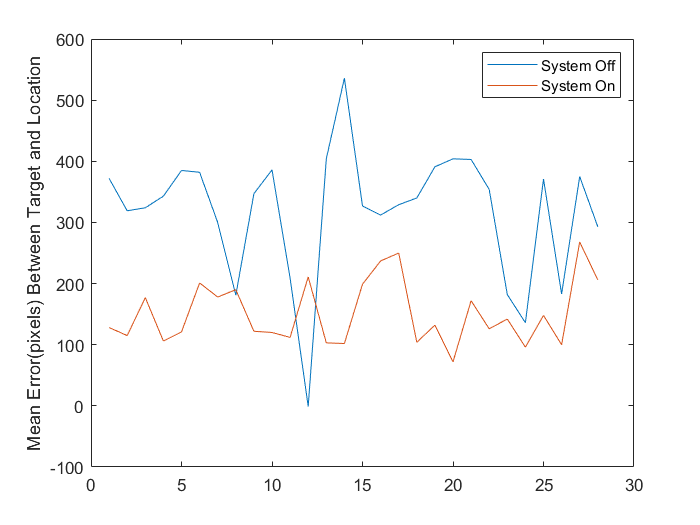

plot(rdata.SystemOff);hold on;
plot(rdata.SystemOn); hold off;
legend('System Off','System On')
ylabel("Mean Error(pixels) Between Target and Location")

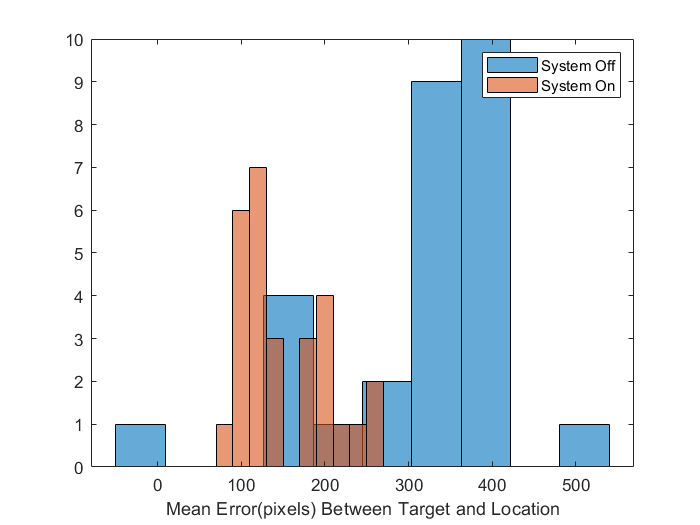


histogram(rdata.SystemOff, 10); hold on; 
histogram(rdata.SystemOn, 10); hold off;
legend('System Off','System On')
xlabel("Mean Error(pixels) Between Target and Location")

### Find and Remove Invalid Data

I chose to just delete the data point(s) that had invalid values (like -1, since it is impossible to have an error of -1 pixels), because I did not think that I could reasonably esimate the correct value for that measurement.

% look for invalid values
min(rdata.SystemOff) % this is originally -1

ans = -1

min(rdata.SystemOn)

ans = 72


rdata([find(rdata.SystemOff == -1)],:) = [];

min(rdata.SystemOff) % make sure removal worked

ans = 136

### State what you are trying to answer

I am trying to determine if the Argus implant actually works. The data contains column vectors containing the mean difference between the subject's guess at where the square was on the screen, and the actual location of the square for two conditions: the implant is turned on, and the implant is turned off. These variables are discrete measurements, and there is one value for each condition per participant. 

The question I am trying to answer is, **are users of the implant able to locate a square on the screen with less error when the implant is turned on? **

The null hypothesis in this scenario would be that the implant has no effect on the ability of users to locate the square on the screen. 

The alternative hypothesis is that the implant being turned on allows users to more accurately locate the square on the screen. 

### Determine what types of tests/measurements are appropriate to answer your question

Based on the flow chart provided, I think that I should use a related sample t-test. The data came from repeated measures/matched samples, because the same test was given to multiple different people under the same two conditions. There are two scores for each person (one score per condition). All of these factors put together suggest that a related sample t test (also called paired t-test), is the most appropriate test to test the null hypothesis. This conclusion is confirmed by some more sources that I have looked up, which say that this test is often used for testing the same sample group before and after a treatment, which is very similar to what happened in this study.

Assumptions:

- Data: x1, x2, . . . , xn and y1, y2, . . . , yn must have the same length.

- The data, i.e., the differences for the matched-pairs, follow a normal probability distribution.

#### Check Assumptions about dataset are correct

% check that length of datasets are same
length(rdata.SystemOn) 

ans = 27

length(rdata.SystemOff)

ans = 27


% check if distributions are normal (0 means yes)
adtest(rdata.SystemOn)

ans = logical
   1


adtest(rdata.SystemOff)

ans = logical
   1


### Calculate appropriate measurements and tests

[h,p,ci,stats] = ttest(rdata.SystemOn, rdata.SystemOff)

h = 1

p = 1.5414e-09

ci =  -220.8221
 -139.2520


stats = struct with fields:
    tstat: -9.0737
       df: 26
       sd: 103.1002


### Generate a figure/graph to illustrate your question

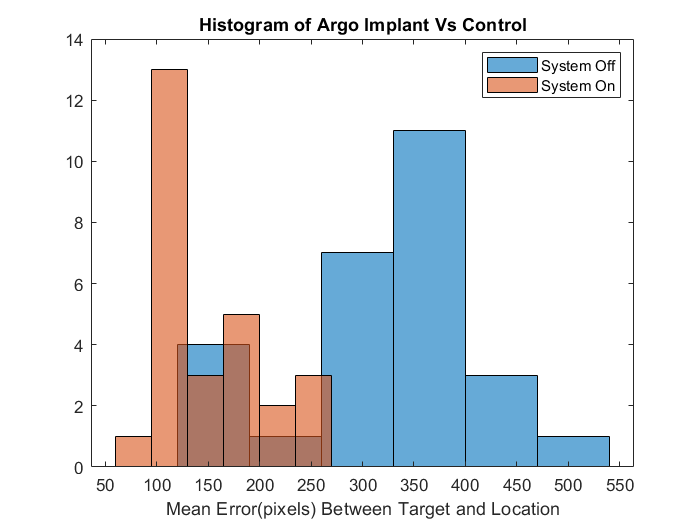

histogram(rdata.SystemOff, 6); hold on; 
histogram(rdata.SystemOn, 6); hold off;
legend('System Off','System On')
xlabel("Mean Error(pixels) Between Target and Location")
title("Histogram of Argo Implant Vs Control")


meanOn = mean(rdata.SystemOn)

meanOn = 149.1481

meanOff = mean(rdata.SystemOff)

meanOff = 329.1852

dif = meanOff - meanOn

dif = 180.0370

### Summarize your findings in words

I reject the null hypothesis (p≤0.05)

According to the results of the t test, the p value is 1.5414e-09, which means that there is a 1.5414e-09/1 chance that the results of the study could have been obtained if the treatment does not have an effect. 

## Dataset 2: MagStimVis

clear all;
mdata = readtable("MagStimVis.txt");

### Plot Data

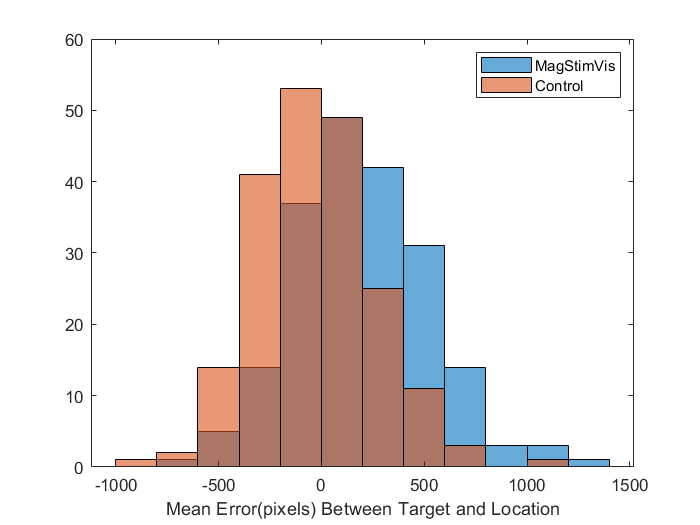

histogram(mdata.MagStimVis);
hold on; 
histogram(mdata.Control);
hold off;
legend('MagStimVis','Control')
xlabel("Mean Error(pixels) Between Target and Location")

### Find and Remove Invalid Data

There do not appear to be any invalid data points or extreme outliers, and the histogram confirms this. 

% search for outliers
min(mdata.MagStimVis)

ans = -680.2000

min(mdata.Control)

ans = -918.9000

max(mdata.MagStimVis)

ans = 1.2453e+03

max(mdata.Control)

ans = 1.0293e+03

### State what you are trying to answer

This data contains column vectors which contain information from a very similar test to the one used by the Argus implant test. **Are users of the implant able to locate a square on the screen with less error when the implant is turned on? **

The null hypothesis is: The MagStimVis treatment has no effect on the ability of users to locate the square on the screen. 

The alternative hypothesis is: The treatment allows users to more accurately locate the square on the screen. 

### Determine what types of tests/measurements are appropriate to answer your question

This data is very similar to the last dataset, except that the participants from the MagStimVis condition is not the same as the participants in the control condition. Therefore I will use an independent measures t test. 

Assumptions:

- Both groups of data are independent normal samples

% check if distributions are normal (0 means yes)
adtest(mdata.MagStimVis)

ans = logical
   0


adtest(mdata.Control)

ans = logical
   0


### Calculate appropriate measurements and tests

[h, p, sig,ci] = ttest2(mdata.MagStimVis, mdata.Control)

h = 1

p = 1.3227e-12

sig =   165.9952
  287.7428


ci = struct with fields:
    tstat: 7.3268
       df: 398
       sd: 309.6419


### Generate a figure/graph to illustrate your question

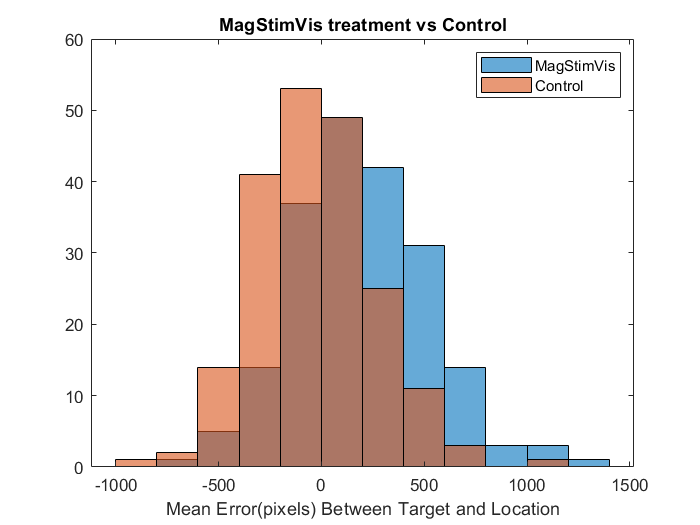

histogram(mdata.MagStimVis);
hold on; 
histogram(mdata.Control);
hold off;
legend('MagStimVis','Control')
xlabel("Mean Error(pixels) Between Target and Location")
title("MagStimVis treatment vs Control")


meanMag = mean(mdata.MagStimVis)

meanMag = 196.3795

meanCon = mean(mdata.Control)

meanCon = -30.4895

dif = meanCon - meanMag 

dif = -226.8690

### Summarize your findings in words

I reject the null hypothesis (p≤0.05).

The p value represents the chance of the given results occuring if the null hypothesis is correct. I calculated a p value of 1.3227e-12, which shows that is is very likely that the MagStimVis treatment is effective.